# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 박종서**

**학번**** : 201710919**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

n = -200 : 1 : 200;
x1 = cos(0.49*pi*n);
x2 = cos(0.51*pi*n);
x3 = 5*(x1+x2);
figure(1)
subplot(2,1,1)
stem(n,x3)
xlabel('n');
ylabel('xn');


2) 

n = 0:1:100;
x1 = exp(-0.05*n);
x2 = 0.1*pi*n; 
x3 = (pi/3)*ones(1,length(n));
x4 = x2+x3;
x5 = sin(x4);
x6 = x1.*x5;

x6 =     0.8660    0.9304    0.8999    0.7863    0.6084    0.3894    0.1540   -0.0737   -0.2726   -0.4267   -0.5253   -0.5643   -0.5458   -0.4769   -0.3690   -0.2362   -0.0934    0.0447    0.1654    0.2588    0.3186    0.3423    0.3310    0.2893    0.2238    0.1433    0.0567   -0.0271   -0.1003   -0.1570   -0.1932   -0.2076   -0.2008   -0.1754   -0.1358   -0.0869   -0.0344    0.0164    0.0608    0.0952    0.1172    0.1259    0.1218    0.1064    0.0823    0.0527    0.0208   -0.0100   -0.0369   -0.0577


subplot(2,1,2)
stem(n,x6)
xlabel('n');
ylabel('xn');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

n = 0:100;
a = [1, -0.5, 0.25];
b = [1, 2, 0, 1];
H = impz(b,a,n);
figure(2)
subplot(2,1,1)
stem(n,H)
xlabel('n');
ylabel('H');

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

a = sum(abs(H));

ans = 5.8571

if (a <= abs(10000))
    a = '안정성이 있습니다.'
else
    a = '안정성이 없습니다.'
end
a = sum(abs(H));

3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

n = 0:200;
x = 5 + 3*cos(0.2*pi*n) + 4*sin(0.6*pi*n);
y = filter(b,a,x);
subplot(2,1,2)
stem(n,y)
xlabel('n');
ylabel('y');

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

k = 25;
n = 0:k;
x = (0.8).^n;
nh = n;
h = (-0.9).^n;
y = conv(x,h);
m = 0:50;
figure(3)
subplot(1,3,1)
stem(m,y);
xlabel('m');
ylabel('y');

다음 사용 중 오류가 발생함: stem (43번 라인)
X는 Y와 길이가 동일해야 합니다.

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

k = 25;
n = 0:k;
x = (0.8).^n;
nh = n;
h = (-0.9).^nh;
y = conv(x,h);
m =0:2*k;
subplot(1,3,2)
stem(m,y)
xlabel('m');
ylabel('y');

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

b = [1];
a = [1,-0.8];
n = 0:50;
x = (-0.9).^n;
y = filter(b,a,x);
subplot(1,3,3)
stem(n,y)
xlabel('n');
ylabel('y');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

K = 100;
n = -100:100;
w = n*pi/K;
h = (1 - (0.9)*(0.9)) ./ (1 - 2*(0.9)*cos(w) + (0.9)^2);
magH = abs(h);
angH = angle(h);
figure(4)
subplot(2,1,1);
stem(w/pi,magH);
xlabel('w/pi');
ylabel('magH');
subplot(2,1,2);
stem(w/pi,angH/pi);
xlabel('w/pi');
ylabel('angH/pi');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

K = 100;
n = -100:100;
w = n*pi/K;
h1 = exp(j*w)./(exp(j*w)-0.5);
h2 = exp(j*w)./(exp(j*w)-0.4);
h=h1+h2;
magH = abs(h);
angH = angle(h);
subplot(2,1,2);
stem(w/pi,magH);
xlabel('w/pi');
ylabel('magH');
subplot(2,1,2)
stem(w/pi,angH/pi);
xlabel('w/pi');
ylabel('angH/pi');

5. (P3.17) 

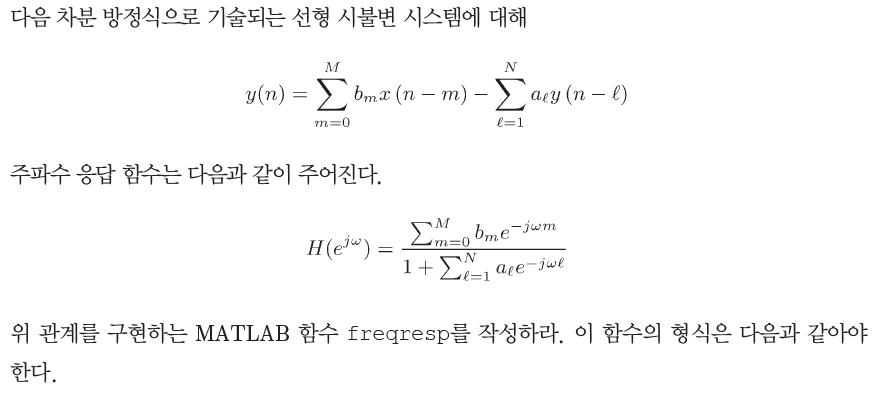

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array
m = 0:length(b)-1;
l = 0:length(a)-1;
num = b*exp(-j*m'*w);
den = a*exp(-j*l'*w);
[H] = num./den;
end

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

b = [1,0,-1];
a = [1,-0.95,0.9025];
m = 0:length(b)-1;
l = 0:length(a)-1;
K = 500;
k = 0:1:K;
w = pi*k/K;
num = b*exp(-j*m'*w);
den = a*exp(-j*l'*w);
H = num./den;
magH = abs(H);
angH = angle(H);
figure(1)
subplot(2,1,1);
plot(w/pi,magH);grid;
xlabel('w/pi');
ylabel('magH/pi');
subplot(2,1,2);
plot(w/pi,angH/pi);grid;
xlabel('w/pi');
ylabel('angH/pi');

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

g = 0:5;
a = (0.5).^g
b = [1];
m = 0:length(b)-1;
l = 0:length(a)-1;
K = 500;
k = 0:1:K;
w = pi*k/K;
num = b*exp(-j*m'*w);
den = a*exp(-j*l'*w);
H = num./den;
magH = abs(H);
angH = angle(H);
subplot(2,1,1);
plot(w/pi,magH);grid;
xlabel('w/pi');
ylabel('magH/pi');
subplot(2,1,2);
plot(w/pi,angH/pi);grid;

스크립트의 함수 정의는 파일의 끝에 표시되어야 합니다.
"freqresp" 함수 정의 뒤에 있는 모든 명령문을 첫 번째 로컬 함수 정의 앞으로 이동하십시오.

xlabel('w/pi');
ylabel('angH/pi');